% Species Prediction
files = dir("history_data/*_history.csv")

files = 8×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


names = string.empty(length(files), 0);
for i = 1:length(files)
     names(i) = files(i).name;
end
names = names'

names = 8×1 string array
    "characteristic_bolete.h5_history.csv"
    "characteristic_bolete_lowres.h5_history.csv"
    "characteristic_final_bolete.h5_history.csv"
    "characteristic_final_bolete_lowres.h5_history.csv"
    "direct_bolete.h5_history.csv"
    "direct_bolete_lowres.h5_history.csv"
    "direct_final_bolete.h5_history.csv"
    "direct_final_bolete_lowres.h5_history.csv"


f = "characteristic_bolete.h5_history.csv"

f = "characteristic_bolete_lowres.h5_history.csv"

f = "characteristic_final_bolete.h5_history.csv"

t = 40×5 table
    Var1    train_acc    train_loss    val_acc    val_loss
    ____    _________    __________    _______    ________

      0      0.68459      0.59477        0.701    0.58289 
      1      0.70839      0.56764      0.70185    0.57457 
      2      0.71123      0.56286      0.70485    0.57057 
      3      0.71304      0.55949       0.7064    0.56838 
      4       0.7155      0.55663      0.70645    0.56649 
      5      0.71598      0.55435      0.70673    0.56498 
      6      0.71723      0.55216      0.70762    0.56353 
      7      0.71878      0.54973      0.70804    0.56226 
      8      0.72118      0.54783       0.7086     0.5616 
      9      0.72069      0.54611      0.70795    0.56035 
     10      0.72245      0.54425      0.70856    0.55974 
     11      0.72172       0.5437      0.70888 

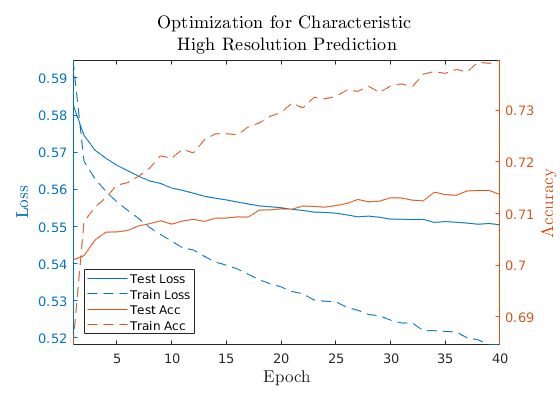

f = "characteristic_final_bolete_lowres.h5_history.csv"

t = 40×5 table
    Var1    train_acc    train_loss    val_acc    val_loss
    ____    _________    __________    _______    ________

      0       0.6825      0.59479      0.70049    0.57917 
      1      0.71024      0.56396      0.70232    0.57183 
      2      0.71494      0.55696      0.70466    0.56805 
      3      0.71818      0.55199      0.70616    0.56566 
      4      0.72186      0.54698      0.70701      0.564 
      5      0.72436      0.54353      0.70785    0.56264 
      6      0.72549      0.54027      0.70832    0.56123 
      7        0.728      0.53644      0.70949     0.5602 
      8      0.72941      0.53378      0.71132    0.55958 
      9      0.73072      0.53173      0.71039    0.55868 
     10      0.73398      0.52874      0.71156    0.55836 
     11      0.73306      0.52799      0.71207 

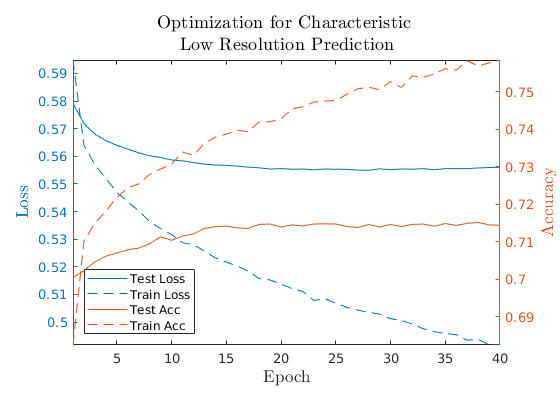

f = "direct_bolete.h5_history.csv"

f = "direct_bolete_lowres.h5_history.csv"

f = "direct_final_bolete.h5_history.csv"

t = 15×5 table
    Var1    train_acc    train_loss    val_acc     val_loss
    ____    _________    __________    ________    ________

      0     0.014537       5.8596      0.030303     5.1222 
      1     0.052793       4.6551      0.053476     4.8488 
      2      0.12624       4.0831      0.071301     4.6453 
      3      0.21959       3.5832      0.094474     4.5095 
      4      0.29992       3.1511       0.13012     4.3702 
      5      0.41239       2.7598       0.14617     4.2743 
      6      0.50115       2.4127       0.16221     4.1933 
      7      0.56695       2.1673       0.16934     4.1543 
      8      0.63581       1.9071       0.17469     4.1143 
      9      0.68554       1.6695       0.17825     4.1078 
     10      0.72609       1.5087       0.19073     4.0407 
     11      0.76817       1.3317 

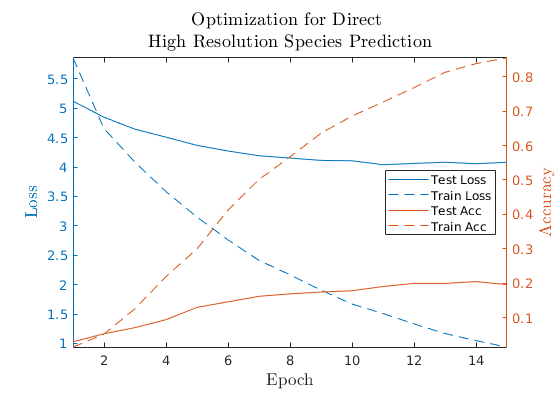

f = "direct_final_bolete_lowres.h5_history.csv"

t = 7×5 table
    Var1    train_acc    train_loss    val_acc     val_loss
    ____    _________    __________    ________    ________

     0      0.022953       5.6913      0.053476      4.828 
     1       0.20735       3.6636      0.085561     4.5407 
     2       0.43305       2.6756       0.11586     4.3808 
     3       0.63122       1.9585       0.13547     4.2971 
     4       0.77047       1.4214        0.1426     4.2526 
     5       0.85004       1.0459       0.15508     4.2536 
     6       0.89977      0.77598       0.16399     4.2683 


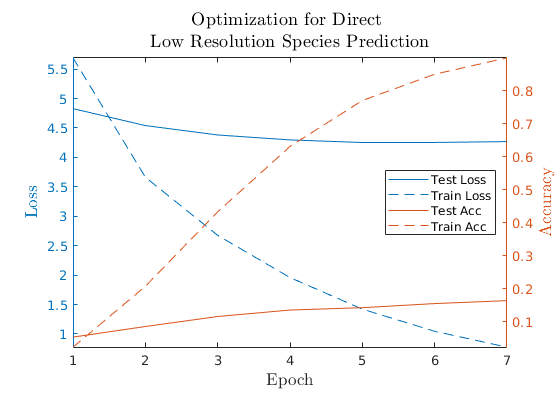


% files = dir("history_data_ed/*_history.csv")
% ed_names = string.empty(length(files), 0);
% for i = 1:length(files)
%      ed_names(i) = files(i).name;
% end
% ed_names = ed_names'
% 
% names = [names;ed_names]

for i= 1:length(names)
    f = names(i)
    if ~contains(f, "_final")
        continue
    end
    t = readtable("history_data/"+f)
    fig = plotCurves(t, title_from_suffix(f));
    saveas(fig, "plots/" + replace(title_from_suffix(f), newline, "") + ".png");
end


% Edibility

files = dir("history_data_ed/*_history.csv")

files = 4×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


ednames = string.empty(length(files), 0);
for i = 1:length(files)
     ednames(i) = files(i).name;
end
ednames = ednames'

ednames = 4×1 string array
    "direct_ed_bolete.h5_history.csv"
    "direct_ed_bolete_lowres.h5_history.csv"
    "direct_ed_final_bolete.h5_history.csv"
    "direct_ed_final_bolete_lowres.h5_history.csv"


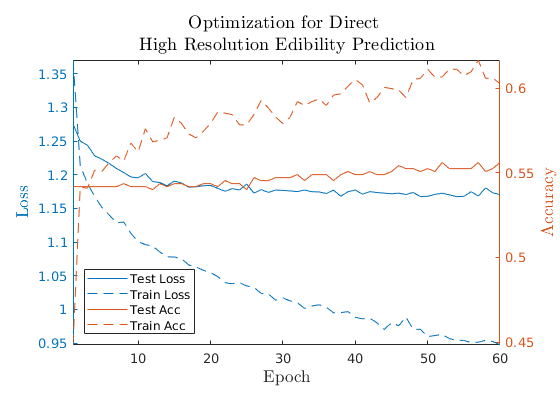

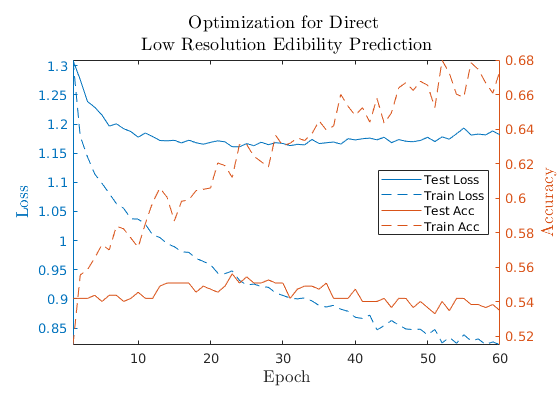

for i= 1:length(ednames)
    f = ednames(i);
    if ~contains(f, "_final")
        continue
    end
    t = readtable("history_data_ed/"+f);
    fig = plotCurves(t, title_from_suffix("history_data_ed/"+f));
    saveas(fig, "plots/" + replace(title_from_suffix("history_data_ed/"+f), newline, "") + ".png");
end

function fig = plotCurves(t, name)
    fig = figure();
%     fig = figure( "Units","normalized", "Position",[0,0,0.4,0.25]);
    yyaxis left
    plotCurve(t.train_loss, t.val_loss, "Loss");
    hold on
    yyaxis right
    plotCurve(t.train_acc, t.val_acc, "Accuracy");
    hold off
    if contains(name, "direct", "IgnoreCase", true) && ~contains(name, "edibility", "IgnoreCase", true) || ...
            contains(name, "direct", "IgnoreCase", true) && contains(name, "edibility", "IgnoreCase", true) && contains(name, "low", "IgnoreCase", true)
        loc = "east";
    else
        loc = "southwest";
    end
    
    legend(["Test Loss","Train Loss",...
        "Test Acc","Train Acc"], "Location",loc)
    title(name,"Interpreter", "latex" ,"FontSize",14)
    pbaspect([1.5,1,1])
    axis tight
end
function plotCurve(train, val, type)
    plot(val)
    hold on
    plot(train)
    hold off
    ylabel(type,"Interpreter", "latex" ,"FontSize",13)
    xlabel("Epoch","Interpreter", "latex" ,"FontSize",13)
end
function tit = title_from_suffix(suffix)
    tit = "Optimization for ";
    suffix = string(suffix);
    if contains(suffix, "direct")
        tit = tit + "Direct ";
    else
        tit = tit + "Characteristic ";
    end
    tit = tit + newline;
    if contains(suffix, "_bolete.h5")
        tit = tit + "High Resolution";
    else
        tit = tit + "Low Resolution";
    end
    if contains(suffix, "_ed")
        tit = tit + " Edibility Prediction";
    elseif contains(suffix, "direct")
        tit = tit + " Species Prediction";
    else
        tit = tit + " Prediction";
    end
%     if contains(suffix, "_final")
%         tit = tit + " Final";
%     end
end